## Quantitative Methods 3

### Problem Set 2

**Problem 1: Forecasting theory**

ARMA(1,2) process:


$$y_t = c+ \phi_1y_{t-1} + \theta_1\epsilon_{t-1} + \theta_2\epsilon_{t-2} + \epsilon_t , \epsilon_t \sim iid N(0, \sigma^2)$$


- Optimal MSE-point forecast for h=1 and h=2.


$$y_{T+1} = c + \phi_1y_T + \theta_1\epsilon_T + \theta_2\epsilon_{T-1} + \epsilon_{T+1}$$



$$\hat{y_{T+1}} = E_T(\mu + \phi_1(y_T - \mu) + \theta_1 \epsilon_T + \theta_2\epsilon_{T-1} + \epsilon_{T+1})$$



$$\hat{y_{T+1}} = \mu + \phi_1(y_T - \mu ) + \theta_1\epsilon_T + \theta_2\epsilon_{T-1} $$



$$\hat{y_{T+2}}= E_T ( \mu + \phi_1(\mu + \phi_1 (y_T - \mu)+\theta_1\epsilon_T+ \theta_2\epsilon_{T-1} + \epsilon_{T+1})-\mu) + \theta_1\epsilon_{T+1} + \theta_2\epsilon_T+ \epsilon_{T+2}) \\
\hat{y_{T+2}}= \mu + \phi_1^2(y_T - \mu) + \phi_1\theta_1\epsilon_T + \phi_1\theta_2\epsilon_{T-1} + \theta_2\epsilon_T$$


**Problem 3: Forecasting practice**

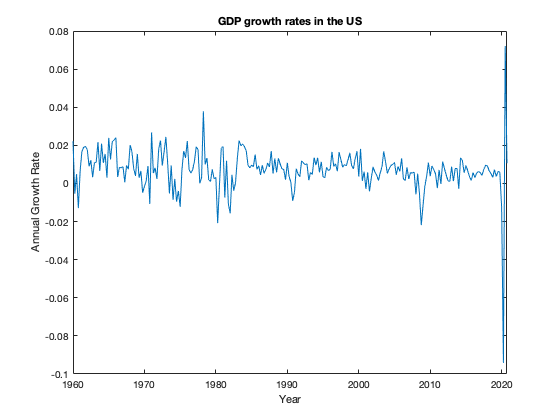

cd('/Users/nesgueven/Master ITFD/Term 3/Quantitative Methods III/');
addpath '/Users/nesgueven/Master ITFD/Term 3/Quantitative Methods III/MatlabIntroBGSE'
GDPC1 = readtable("GDPC1.xls");
gdp = GDPC1(:,"GDPC1");
gdp = double(table2array(gdp));
returns = price2ret(gdp, [], 'Continuous');
T = length(returns);
t = linspace(1,T,T)';
returns = [t, returns];
TT = (datetime(1947,01,01):calmonths(3):datetime(2021,01,01))';
TT = TT(2:end);
% plot
figure;
plot(TT(52:295), returns(52:295,2));
title("GDP growth rates in the US");
xlabel('Year');
ylabel('Annual Growth Rate');

2. Estimate M1 and M2

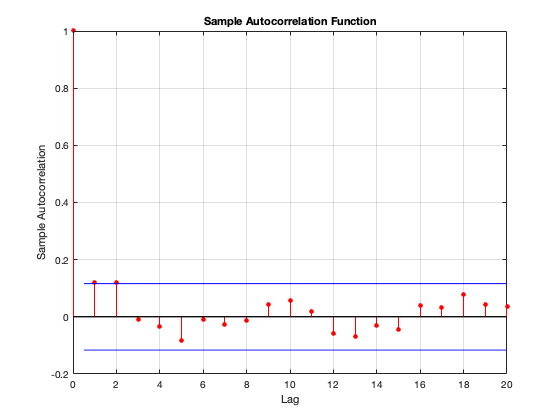

autocorr(returns(52:295,2));

% M1
y = returns(:,2);
N = 244;
onesN = ones(N,1);
X = [onesN, y(51:294,1)];
[bols, res] = ols(X,y(52:295));
sig2hat=(res'*res)/(N-1);
%M2
X_2 = [onesN, y(51:294,1), y(50:293,1)];
[bols2, res2] = ols(X_2, y(52:295));
sig2hat2= (res2'*res2)/(N-2);
% show results
Results = table({'M1';'M2'}, [bols(1);bols2(1)],[bols(2); bols2(2)], [0; bols2(3)],[sig2hat; sig2hat2]);
Results.Properties.VariableNames={'Specification','c', 'Phi 1', 'Phi 2', 'Sigma^2'};
Results

Results = 2×5 table
    Specification        c         Phi 1       Phi 2      Sigma^2  
    _____________    _________    ________    _______    __________

       {'M1'}        0.0071423    0.015048          0    0.00012694
       {'M2'}        0.0063995    0.014088    0.10824    0.00012565


% log-Likelihoods
% M1
GDPC1(1,:) = [];
param = [bols(1), bols(2), sig2hat];
[mu, epsilon] = myar1filter(y,param);
ar1filter = mu + eps;
yt = y(52:295); 
ylag1 = y(51:294);
loglikar1 = -((N)/(2))*log(pi*2)-((N)/(2))*log(param(3))+sum(-(((yt-param(1)-param(2).*ylag1).^2)/2*(param(3))));
